## loading necessary file

clear all
close all
load TR4_data.mat
load TR4_ws_dv_constrain.mat

## plot workspace

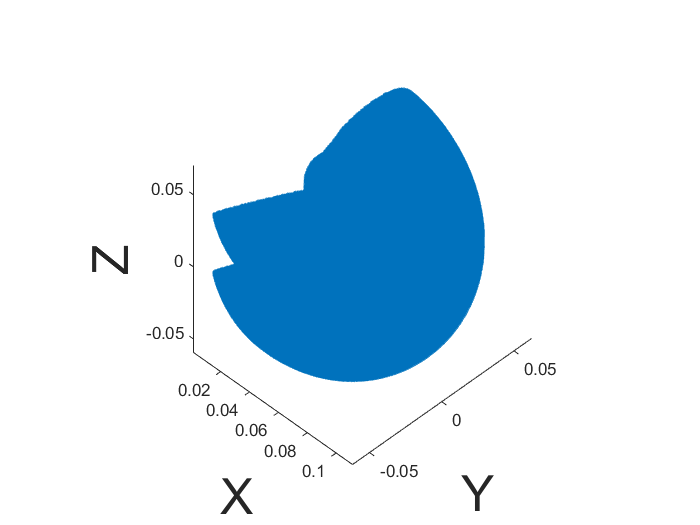

figure(1)
point2plot=nan(3,Xdiv*Ydiv*Zdiv);
point2plot_inner=nan(3,Xdiv*Ydiv*Zdiv);
p=1;
for i = 1:Xdiv
    for j = 1:Ydiv
        for k = 1:Zdiv
            if(space_(i,j,k)==1)
                point2plot(:,p)=[X(i) Y(j) Z(k)]';
                p=p+1;
            end
        end
    end
end
plot3(point2plot(1,:),point2plot(2,:),point2plot(3,:),'.')
axis equal
xlabel('X',"FontSize",30)
ylabel('Y',"FontSize",30)
zlabel('Z',"FontSize",30)
view([45 45])

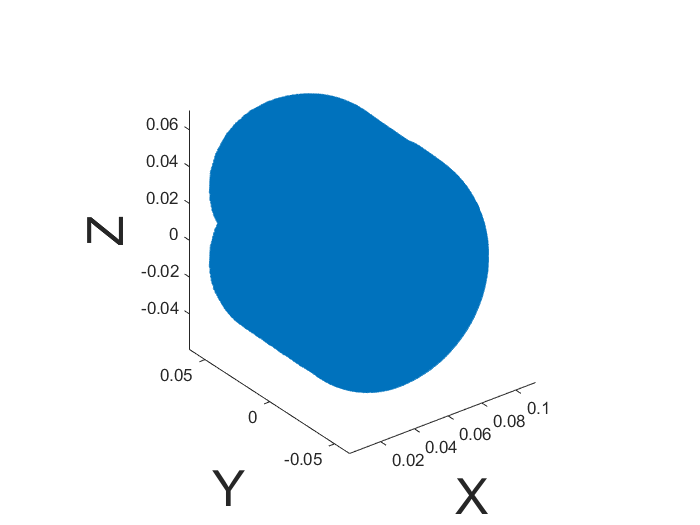

plot3(point2plot(1,:),point2plot(2,:),point2plot(3,:),'.')
axis equal
xlabel('X',"FontSize",30)
ylabel('Y',"FontSize",30)
zlabel('Z',"FontSize",30)

## plot solid

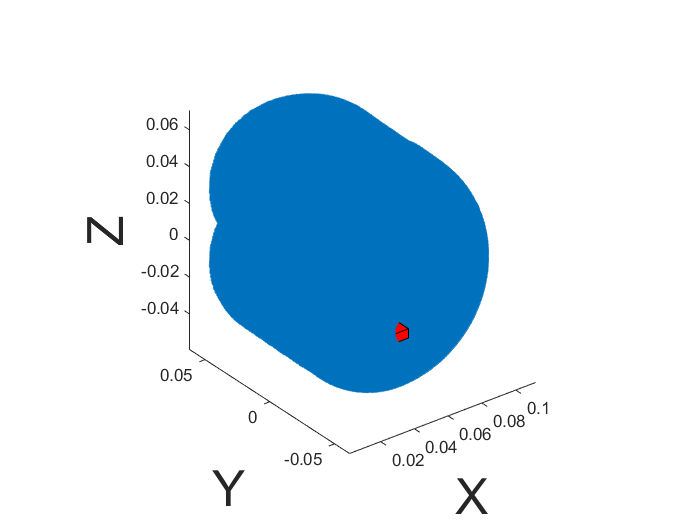

plot_squareXY([0.07 -5e-3 -0.05 1]',10e-3,5e-3,1,'r')

## choose point

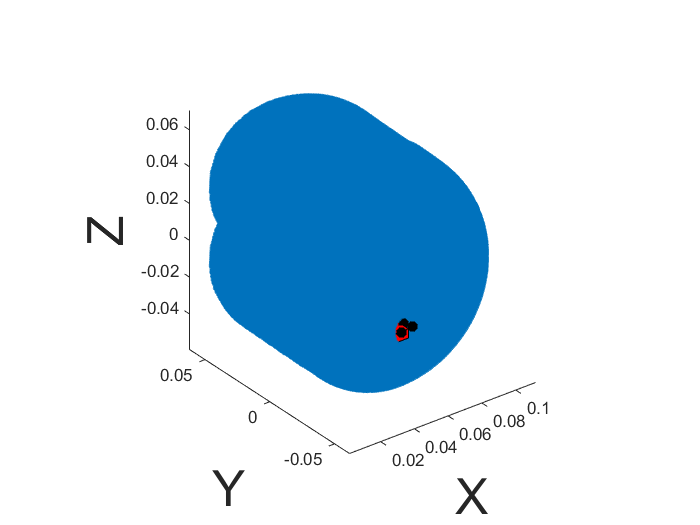

P1=[0.055 0 -0.03 1]';
P2=[0.071 6e-3 -0.045 1]';
P3=[0.079 6e-3 -0.045 1]';
P34=[0.082 4.5e-3 -0.045 1]';
P4=[0.081 0 -0.045 1]';
P45=[0.083 -4.5e-3 -0.045 1]';
P5=[0.075 -6e-3 -0.045 1]';
points=[P1 P2 P3 P34 P4 P45 P5];
hold on
plot3(points(1,:),points(2,:),points(3,:),'*k',"LineWidth",3)

Q=TR4_invNumeric(points(1:3,:),link,1000,Con);

## compute trajectory

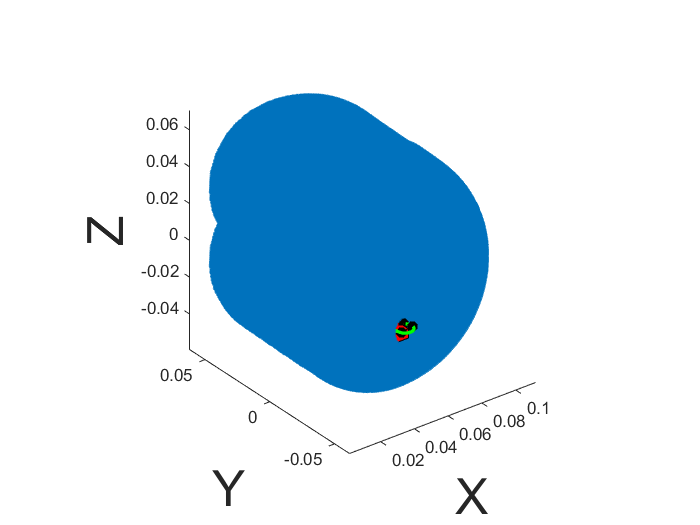

F=zeros(21,1);
[Q1,Qp1,Qpp1,Fq1,T1,X1,Xp1,Xpp1]=TR4_move([P1(1:3) P2(1:3)],1,@Cicloidale,link,M,F,'minimum_time_C',Con);
[Q2,Qp2,Qpp2,Fq2,T2,X2,Xp2,Xpp2]=TR4_move([P2(1:3) P3(1:3)],5,@Cicloidale,link,M,F,'linear',Con,Q1(end,:)');
[Q3,Qp3,Qpp3,Fq3,T3,X3,Xp3,Xpp3]=TR4_move([P3(1:3) P34(1:3) P4(1:3)],5,@Cicloidale,link,M,F,'circular',Con,Q2(end,:)');
[Q4,Qp4,Qpp4,Fq4,T4,X4,Xp4,Xpp4]=TR4_move([P4(1:3) P45(1:3) P5(1:3)],5,@Cicloidale,link,M,F,'circular',Con,Q3(end,:)');
[Q5,Qp5,Qpp5,Fq5,T5,X5,Xp5,Xpp5]=TR4_move([P5(1:3) P1(1:3)],1,@Cicloidale,link,M,F,'minimum_time_C',Con,Q4(end,:)');
plot3(X1(:,1),X1(:,2),X1(:,3),'g',"LineWidth",2)
plot3(X2(:,1),X2(:,2),X2(:,3),'g',"LineWidth",2)
plot3(X3(:,1),X3(:,2),X3(:,3),'g',"LineWidth",2)
plot3(X4(:,1),X4(:,2),X4(:,3),'g',"LineWidth",2)
plot3(X5(:,1),X5(:,2),X5(:,3),'g',"LineWidth",2)

## plot singoli task e debug

TASK1

disp("TASK1")

TASK1


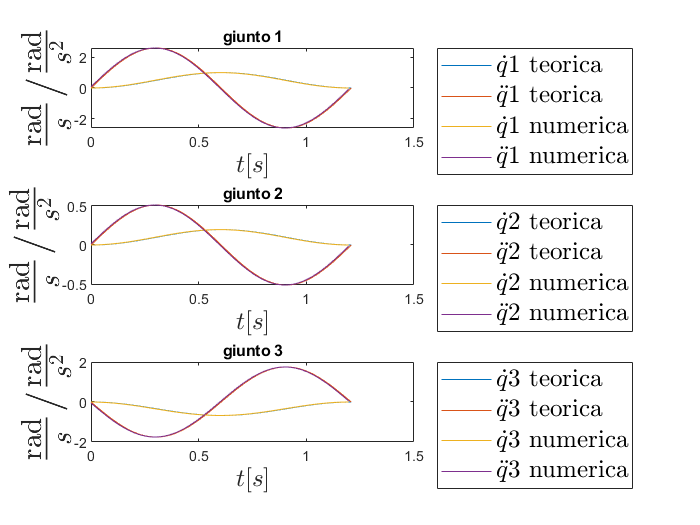

qp1=diff(Q1)/(T1(2)-T1(1));
qpp1=diff(Qp1)/(T1(2)-T1(1));
figure()
for i=1:3
    subplot(3,1,i)
    plot(T1,Qp1(:,i),T1,Qpp1(:,i),T1(1:end-1),qp1(:,i),T1(1:end-1),qpp1(:,i))
    legend("$\dot q$"+int2str(i)+" teorica","$\ddot q$"+int2str(i)+" teorica","$\dot q$"+int2str(i)+" numerica","$\ddot q$"+int2str(i)+" numerica","Location","eastoutside",'Interpreter','latex','FontSize',15)
    title("giunto "+int2str(i))
    xlabel("$t [s]$",'Interpreter','latex','FontSize',15)
    ylabel("$\frac{\mathrm{rad}}{s} / \frac{\mathrm{rad}}{s^2}$",'Interpreter','latex','FontSize',25)
end

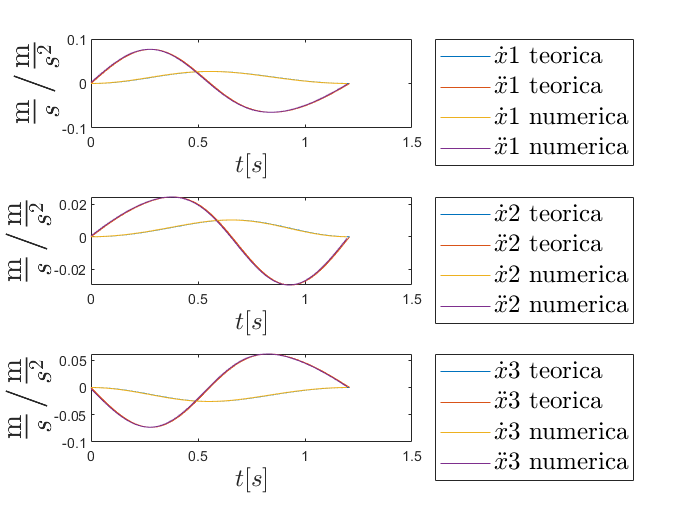

qp1=diff(X1)/(T1(2)-T1(1));
qpp1=diff(Xp1)/(T1(2)-T1(1));
figure()
for i=1:3
    subplot(3,1,i)
    plot(T1,Xp1(:,i),T1,Xpp1(:,i),T1(1:end-1),qp1(:,i),T1(1:end-1),qpp1(:,i))
    legend("$\dot x$"+int2str(i)+" teorica","$\ddot x$"+int2str(i)+" teorica","$\dot x$"+int2str(i)+" numerica","$\ddot x$"+int2str(i)+" numerica","Location","eastoutside",'Interpreter','latex','FontSize',15)
    xlabel("$t [s]$",'Interpreter','latex','FontSize',15)
    ylabel("$\frac{\mathrm{m}}{s} / \frac{\mathrm{m}}{s^2}$",'Interpreter','latex','FontSize',25)
end

TASK2

disp("TASK2")

TASK2


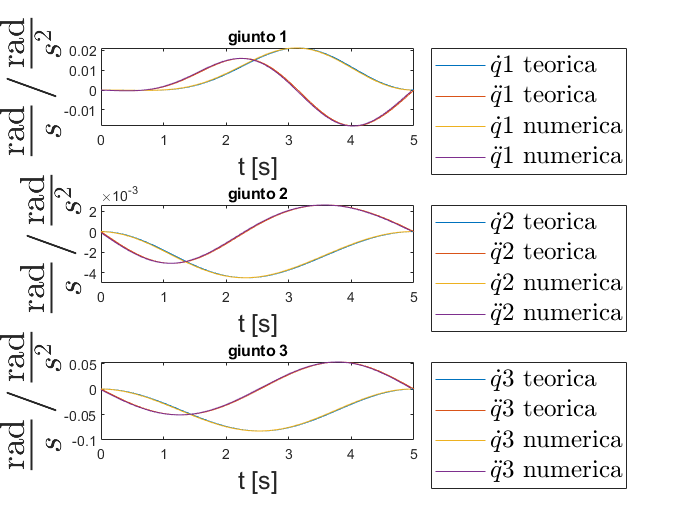

qp2=diff(Q2)/(T2(2)-T2(1));
qpp2=diff(Qp2)/(T2(2)-T2(1));
figure()
for i=1:3
    subplot(3,1,i)
    plot(T2,Qp2(:,i),T2,Qpp2(:,i),T2(1:end-1),qp2(:,i),T2(1:end-1),qpp2(:,i))
    legend("$\dot q$"+int2str(i)+" teorica","$\ddot q$"+int2str(i)+" teorica","$\dot q$"+int2str(i)+" numerica","$\ddot q$"+int2str(i)+" numerica","Location","eastoutside",'Interpreter','latex','FontSize',15)
    title("giunto "+int2str(i))
    xlabel("t [s]",'FontSize',15)
    ylabel("$\frac{\mathrm{rad}}{s} / \frac{\mathrm{rad}}{s^2}$",'Interpreter','latex','FontSize',30)
end

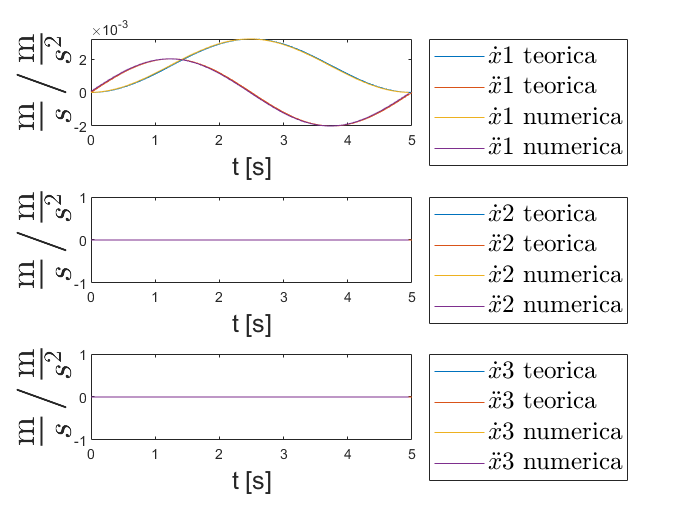

qp2=diff(X2)/(T2(2)-T2(1));
qpp2=diff(Xp2)/(T2(2)-T2(1));
figure()
for i=1:3
    subplot(3,1,i)
    plot(T2,Xp2(:,i),T2,Xpp2(:,i),T2(1:end-1),qp2(:,i),T2(1:end-1),qpp2(:,i))
    legend("$\dot x$"+int2str(i)+" teorica","$\ddot x$"+int2str(i)+" teorica","$\dot x$"+int2str(i)+" numerica","$\ddot x$"+int2str(i)+" numerica","Location","eastoutside",'Interpreter','latex','FontSize',15)
    xlabel("t [s]",'FontSize',15)
    ylabel("$\frac{\mathrm{m}}{s} / \frac{\mathrm{m}}{s^2}$",'Interpreter','latex','FontSize',30)
end

TASK3

disp("TASK3")

TASK3


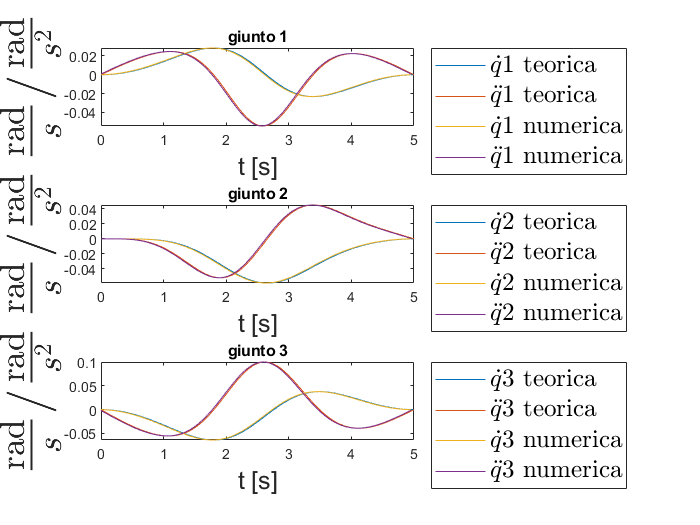

qp3=diff(Q3)/(T3(2)-T3(1));
qpp3=diff(Qp3)/(T3(2)-T3(1));
figure()
for i=1:3
    subplot(3,1,i)
    plot(T3,Qp3(:,i),T3,Qpp3(:,i),T3(1:end-1),qp3(:,i),T3(1:end-1),qpp3(:,i))
    legend("$\dot q$"+int2str(i)+" teorica","$\ddot q$"+int2str(i)+" teorica","$\dot q$"+int2str(i)+" numerica","$\ddot q$"+int2str(i)+" numerica","Location","eastoutside",'Interpreter','latex','FontSize',15)
    title("giunto "+int2str(i))
    xlabel("t [s]",'FontSize',15)
    ylabel("$\frac{\mathrm{rad}}{s} / \frac{\mathrm{rad}}{s^2}$",'Interpreter','latex','FontSize',30)
end

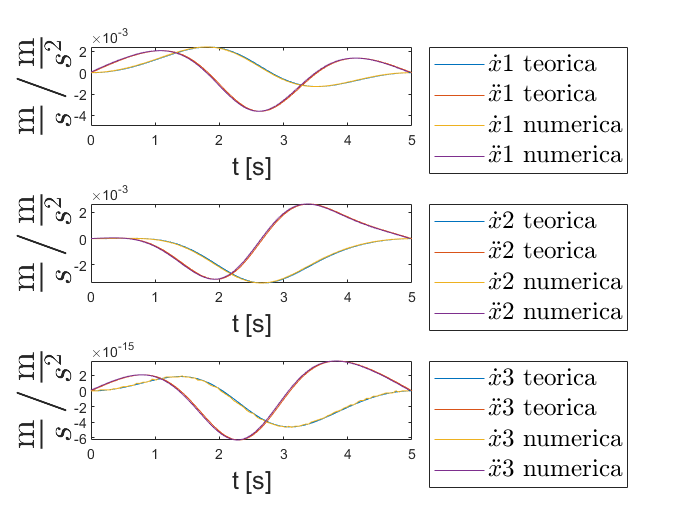

qp3=diff(X3)/(T3(2)-T3(1));
qpp3=diff(Xp3)/(T3(2)-T3(1));
figure()
for i=1:3
    subplot(3,1,i)
    plot(T3,Xp3(:,i),T3,Xpp3(:,i),T3(1:end-1),qp3(:,i),T3(1:end-1),qpp3(:,i))
    legend("$\dot x$"+int2str(i)+" teorica","$\ddot x$"+int2str(i)+" teorica","$\dot x$"+int2str(i)+" numerica","$\ddot x$"+int2str(i)+" numerica","Location","eastoutside",'Interpreter','latex','FontSize',15)
    xlabel("t [s]",'FontSize',15)
    ylabel("$\frac{\mathrm{m}}{s} / \frac{\mathrm{m}}{s^2}$",'Interpreter','latex','FontSize',30)
end

TASK4

disp("TASK4")

TASK4


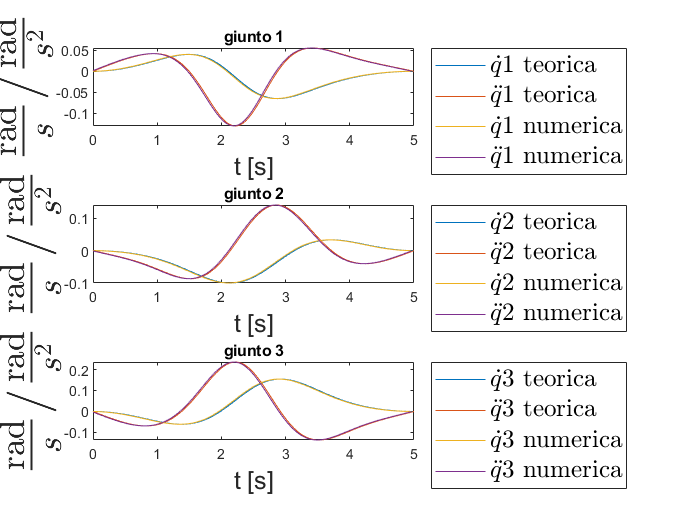

qp4=diff(Q4)/(T4(2)-T4(1));
qpp4=diff(Qp4)/(T4(2)-T4(1));
figure()
for i=1:3
    subplot(3,1,i)
    plot(T4,Qp4(:,i),T4,Qpp4(:,i),T4(1:end-1),qp4(:,i),T4(1:end-1),qpp4(:,i))
    legend("$\dot q$"+int2str(i)+" teorica","$\ddot q$"+int2str(i)+" teorica","$\dot q$"+int2str(i)+" numerica","$\ddot q$"+int2str(i)+" numerica","Location","eastoutside",'Interpreter','latex','FontSize',15)
    title("giunto "+int2str(i))
    xlabel("t [s]",'FontSize',15)
    ylabel("$\frac{\mathrm{rad}}{s} / \frac{\mathrm{rad}}{s^2}$",'Interpreter','latex','FontSize',30)
end

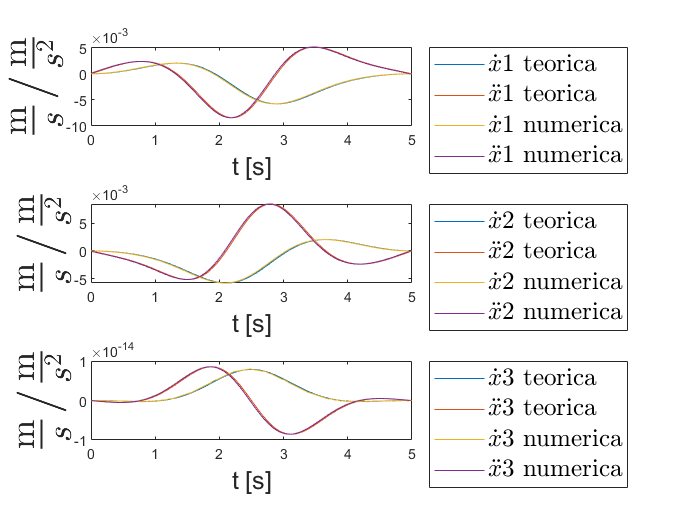

qp4=diff(X4)/(T4(2)-T4(1));
qpp4=diff(Xp4)/(T4(2)-T4(1));
figure()
for i=1:3
    subplot(3,1,i)
    plot(T4,Xp4(:,i),T4,Xpp4(:,i),T4(1:end-1),qp4(:,i),T4(1:end-1),qpp4(:,i))
    legend("$\dot x$"+int2str(i)+" teorica","$\ddot x$"+int2str(i)+" teorica","$\dot x$"+int2str(i)+" numerica","$\ddot x$"+int2str(i)+" numerica","Location","eastoutside",'Interpreter','latex','FontSize',15)
    xlabel("t [s]",'FontSize',15)
    ylabel("$\frac{\mathrm{m}}{s} / \frac{\mathrm{m}}{s^2}$",'Interpreter','latex','FontSize',30)
end

TASK5

disp("TASK5")

TASK5


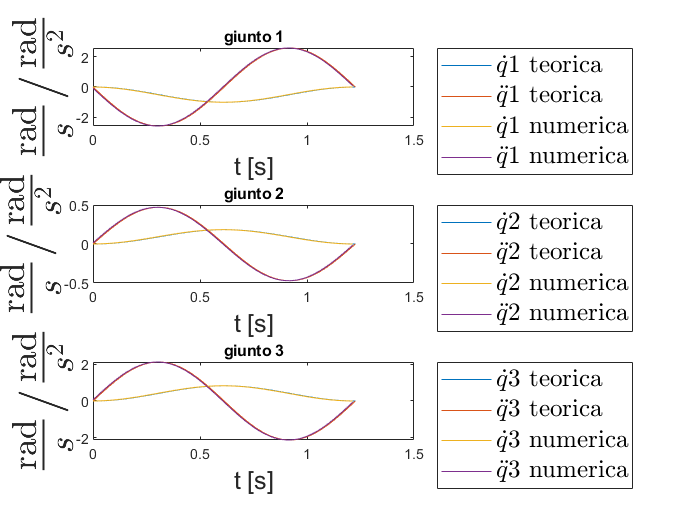

qp5=diff(Q5)/(T5(2)-T5(1));
qpp5=diff(Qp5)/(T5(2)-T5(1));
figure()
for i=1:3
    subplot(3,1,i)
    plot(T5,Qp5(:,i),T5,Qpp5(:,i),T5(1:end-1),qp5(:,i),T5(1:end-1),qpp5(:,i))
    legend("$\dot q$"+int2str(i)+" teorica","$\ddot q$"+int2str(i)+" teorica","$\dot q$"+int2str(i)+" numerica","$\ddot q$"+int2str(i)+" numerica","Location","eastoutside",'Interpreter','latex','FontSize',15)
    title("giunto "+int2str(i))
    xlabel("t [s]",'FontSize',15)
    ylabel("$\frac{\mathrm{rad}}{s} / \frac{\mathrm{rad}}{s^2}$",'Interpreter','latex','FontSize',30)
end

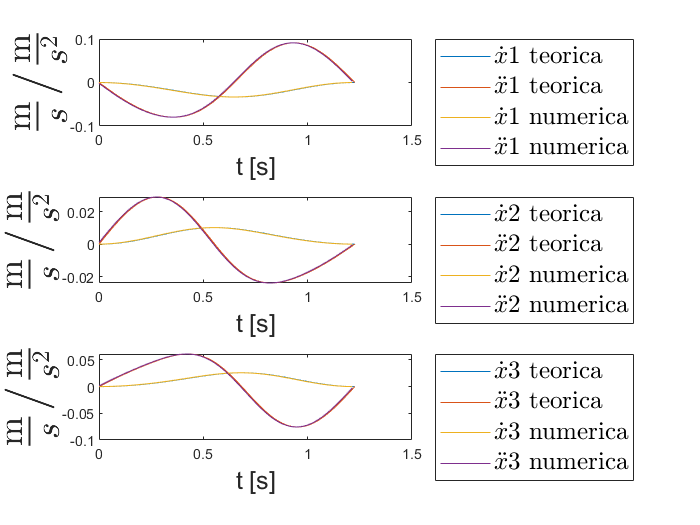

qp5=diff(X5)/(T5(2)-T5(1));
qpp5=diff(Xp5)/(T5(2)-T5(1));
figure()
for i=1:3
    subplot(3,1,i)
    plot(T5,Xp5(:,i),T5,Xpp5(:,i),T5(1:end-1),qp5(:,i),T5(1:end-1),qpp5(:,i))
    legend("$\dot x$"+int2str(i)+" teorica","$\ddot x$"+int2str(i)+" teorica","$\dot x$"+int2str(i)+" numerica","$\ddot x$"+int2str(i)+" numerica","Location","eastoutside",'Interpreter','latex','FontSize',15)
    xlabel("t [s]",'FontSize',15)
    ylabel("$\frac{\mathrm{m}}{s} / \frac{\mathrm{m}}{s^2}$",'Interpreter','latex','FontSize',30)
end

## assemble trajectory with pauses

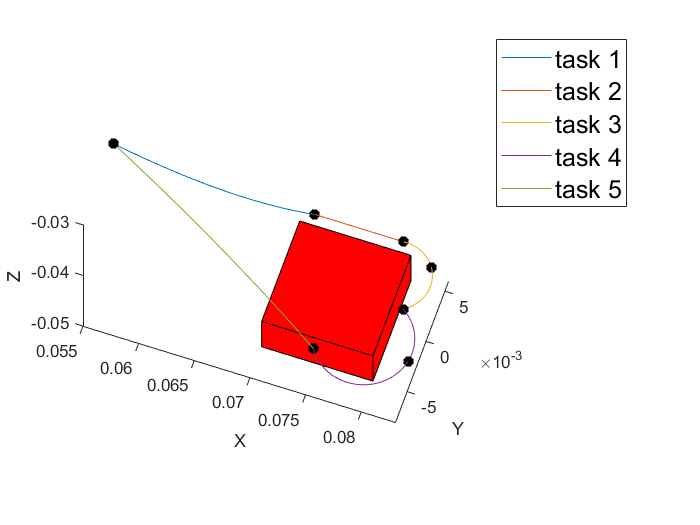

close all
Q_={Q1 Q2 Q3 Q4 Q5};
Qp_={Qp1 Qp2 Qp3 Qp4 Qp5};
Qpp_={Qpp1 Qpp2 Qpp3 Qpp4 Qpp5};
X_={X1 X2 X3 X4 X5};
Xp_={Xp1 Xp2 Xp3 Xp4 Xp5};
Xpp_={Xpp1 Xpp2 Xpp3 Xpp4 Xpp5};
T_={T1 T2 T3 T4 T5};
Fq_={Fq1 Fq2 Fq3 Fq4 Fq5};
[Q,Qp,Qpp,Fq,T,X,Xp,Xpp]=pauses(Q_,Qp_,Qpp_,Fq_,T_,X_,Xp_,Xpp_,1);
% figure
% plot3(X(:,1),X(:,2),X(:,3))
% axis equal
figure
plot3(X1(:,1),X1(:,2),X1(:,3))
hold on
plot3(X2(:,1),X2(:,2),X2(:,3))
plot3(X3(:,1),X3(:,2),X3(:,3))
plot3(X4(:,1),X4(:,2),X4(:,3))
plot3(X5(:,1),X5(:,2),X5(:,3))
plot_squareXY([0.07 -5e-3 -0.05 1]',10e-3,5e-3,1,'r')
plot3(points(1,:),points(2,:),points(3,:),'*k',"LineWidth",3)
legend("task 1","task 2","task 3","task 4","task 5","Location","bestoutside",'FontSize',15)
view([18.8817 64.5391])
axis equal
xlabel("X")
ylabel("Y")
zlabel("Z")

hold off

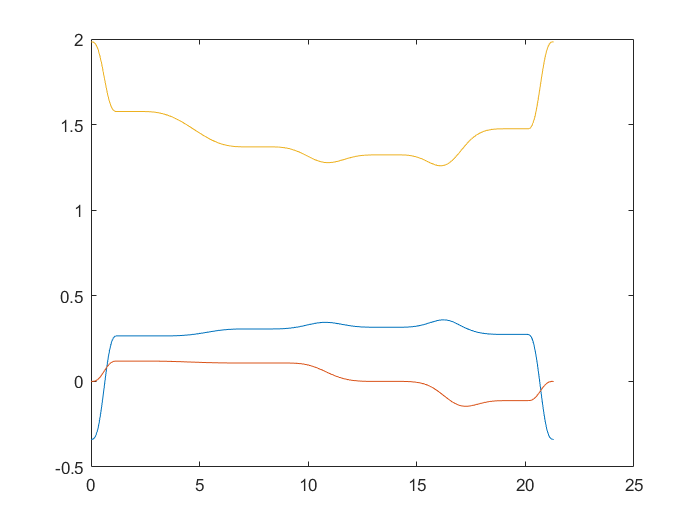

Fqg=zeros(length(Q(:,1)),3);
for index=1:length(Q(:,1))
    Fqg(index,:)=TR4_gravity_compensation(Q(index,:));
end
plot(T,Q(:,1),T,Q(:,2),T,Q(:,3))

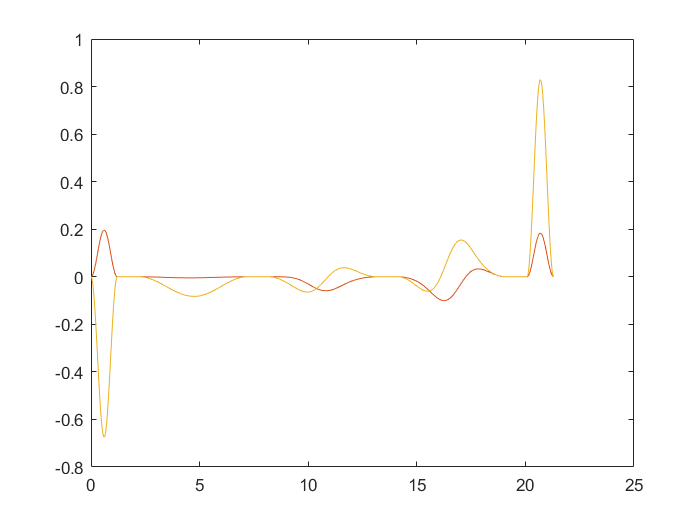

plot(T,Qp(:,2),T,Qp(:,2),T,Qp(:,3))

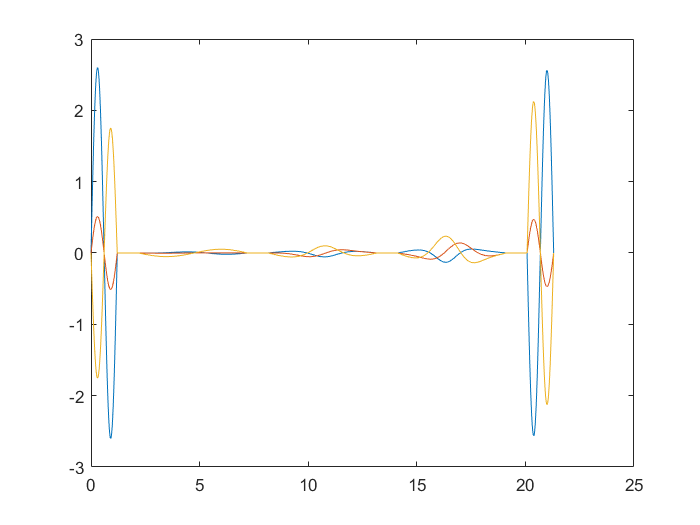

plot(T,Qpp(:,1),T,Qpp(:,2),T,Qpp(:,3))

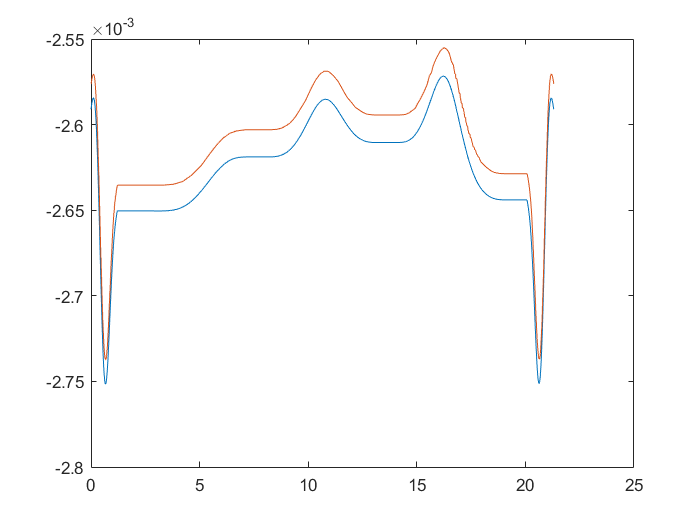

%forze
load out.mat
C1=out.t1_result.Data;
C1_time=out.t1_result.Time;
C2=-out.t2_result.Data;
C2_time=out.t2_result.Time;
C3=out.t3_result.Data;
C3_time=out.t3_result.Time;
plot(T,Fq(:,1))
hold on
plot(T,Fqg(:,1))
hold off

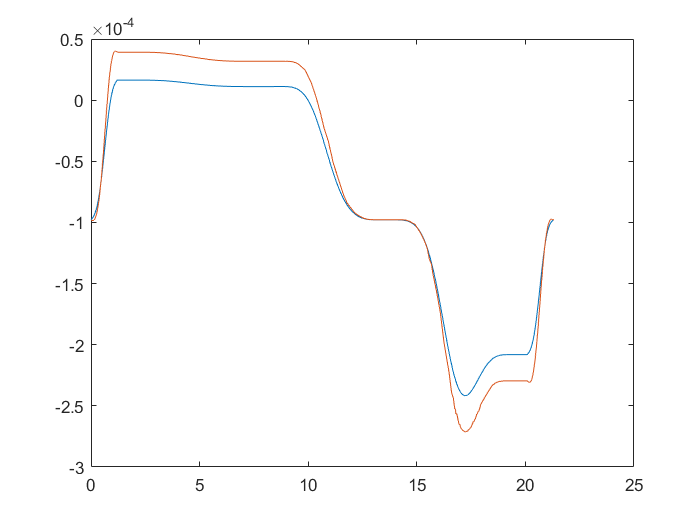

plot(T,Fq(:,2))
hold on
plot(C2_time,C2)
hold off

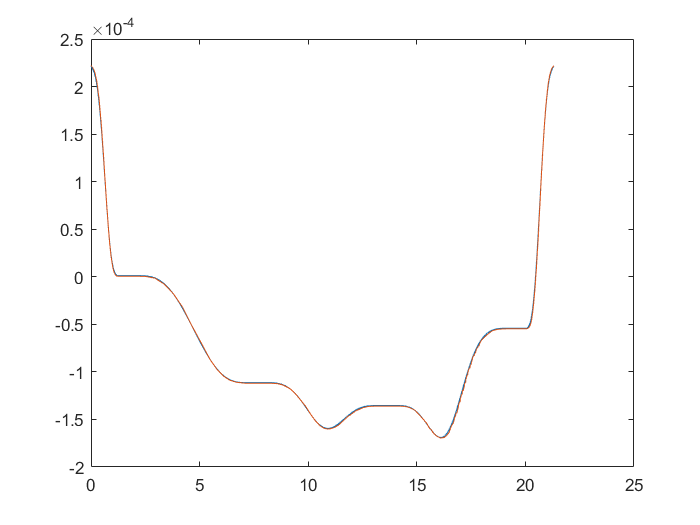

plot(T,Fq(:,3))
hold on
plot(C3_time,C3)
hold off

## save trajectory

save trajectory_data.mat Q Qp Qpp Fq T

## plot trajectory

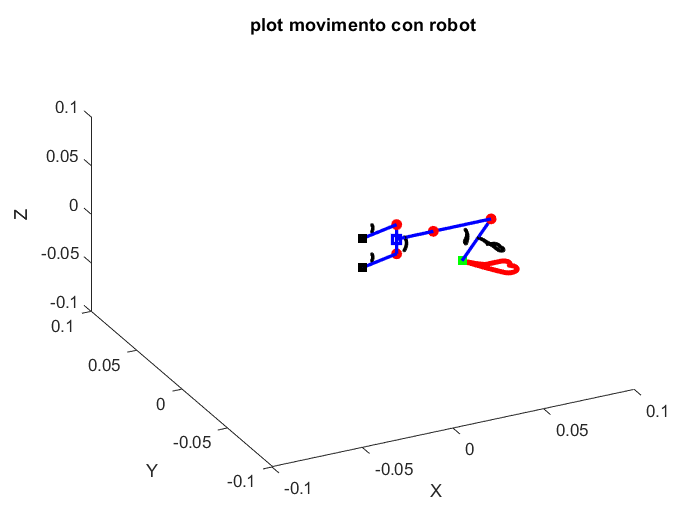

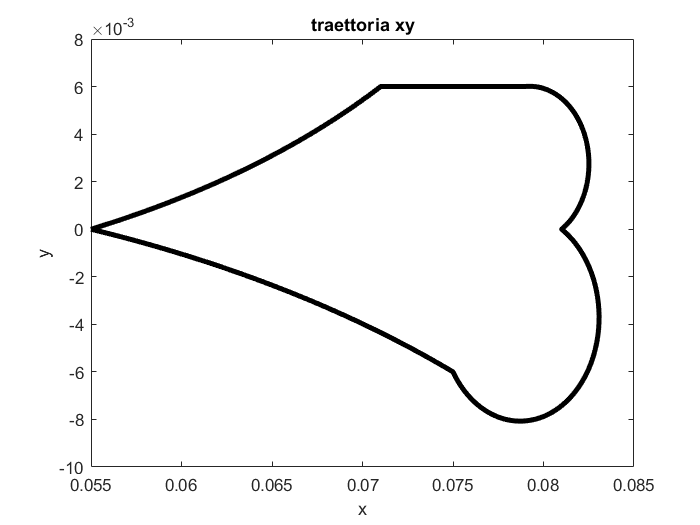

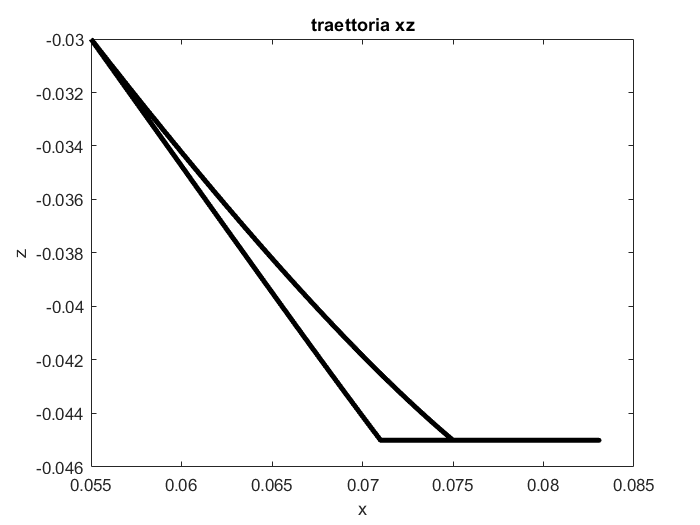

close all
TR4_plot_trajectory(link,Q,10,1)

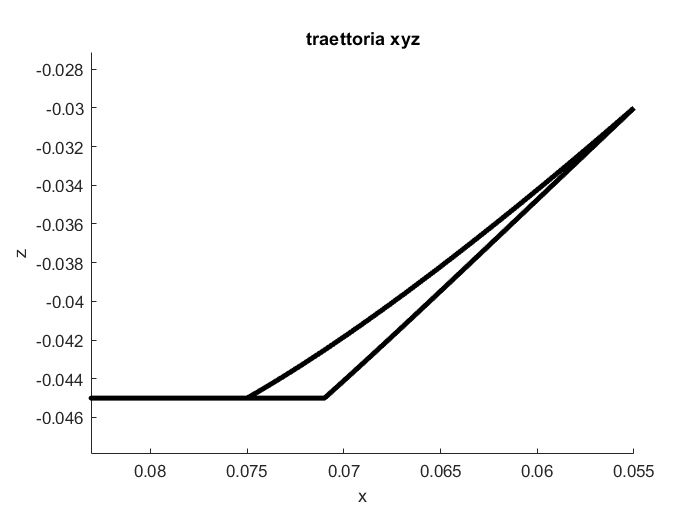

view([0 90 0])
axis equal

## debug forces

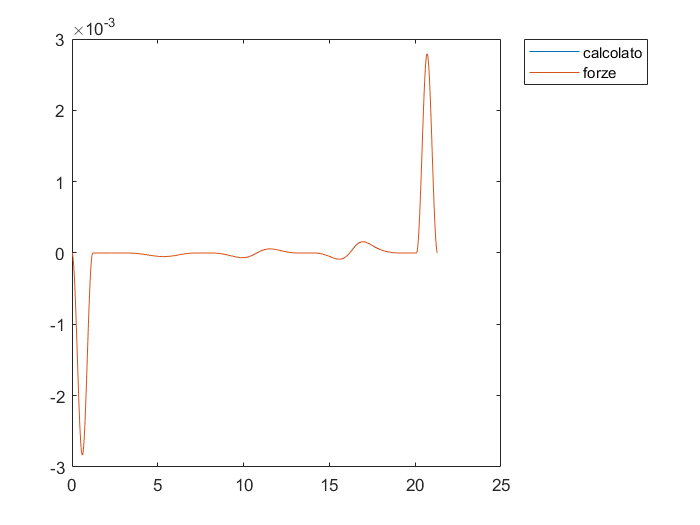

dEt=zeros(1,length(T));
dEt_=zeros(1,length(T));
for i=1:length(T)
    dEt(i)=TR4_dEt(Q(i,:),Qp(i,:),Qpp(i,:));
    dEt_(i)=Fq(i,:)*Qp(i,:)';
end
plot(T,dEt,T,dEt_)
legend('calcolato','forze')

function [Q,Qp,Qpp,Fq,T,X,Xp,Xpp]=pauses(Q_,Qp_,Qpp_,Fq_,T_,X_,Xp_,Xpp_,TOP)
Q=cell2mat(Q_(1));
Qp=cell2mat(Qp_(1));
Qpp=cell2mat(Qpp_(1));
X=cell2mat(X_(1));
Xp=cell2mat(Xp_(1));
Xpp=cell2mat(Xpp_(1));
Fq=cell2mat(Fq_(1));
T=cell2mat(T_(1));

for i=2:length(Q_)
    dt=T(end)-T(end-1);
    division=floor(TOP/dt);
    pause_=(0:dt:division*dt)+T(end);
    T=[T pause_];
    for j=1:division+1
        Q=[Q ;Q(end,:)];
        Qp=[Qp ;Qp(end,:)];
        Qpp=[Qpp ;Qpp(end,:)];
        X=[X;X(end,:)];
        Xp=[Xp;Xp(end,:)];
        Xpp=[Xpp;Xpp(end,:)];
        Fq=[Fq;Fq(end,:)];
    end
    Q=[Q; cell2mat(Q_(i))];
    Qp=[Qp ;cell2mat(Qp_(i))];
    Qpp=[Qpp ;cell2mat(Qpp_(i))];
    X=[X;cell2mat(X_(i))];
    Xp=[Xp;cell2mat(Xp_(i))];
    Xpp=[Xpp;cell2mat(Xpp_(i))];
    Fq=[Fq;cell2mat(Fq_(i))];
    T=[T cell2mat(T_(i))+T(end)];
end
end